clear all
close all
clc

Below is a basic demonstration of the STA / LTA method for detecting earthquakes and allows for quick prototyping of the required filters / thresholds for a single dataset and proving the detection method

% load the data as a csv
data = readtable('Tonhoku_2011_BHZ.csv');

% python data extractor names columns
% "seconds from origin" and "velocity ms"
% use these as the x and y axis of the data
t = data.seconds_from_origin;
velocity_data = data.velocity_m_s;

dt = mean(diff(t));       % time between samples
fs = round(1 / dt);       % sampling frequency
T = t(end) - t(1);        % length

fprintf('Input Data Parameters\n');

Input Data Parameters


fprintf('Sampling frequency:   %d Hz\n', fs);

Sampling frequency:   20 Hz


fprintf('Nyquist frequency:    %.1f Hz\n', fs/2);

Nyquist frequency:    10.0 Hz


fprintf('Signal duration:      %.2f s\n',  T);

Signal duration:      59999.95 s


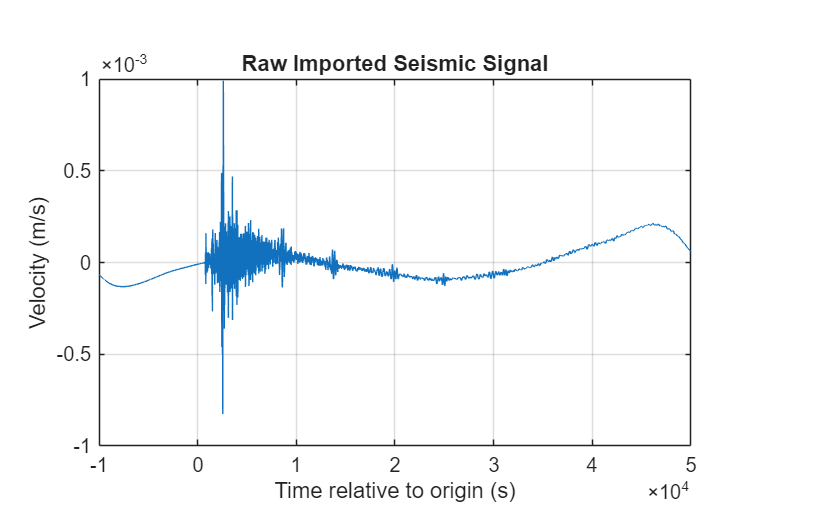


% plot the input signal
figure;
plot(t, velocity_data);
title('Raw Imported Seismic Signal');
xlabel('Time relative to origin (s)'); 
ylabel('Velocity (m/s)');
grid on;

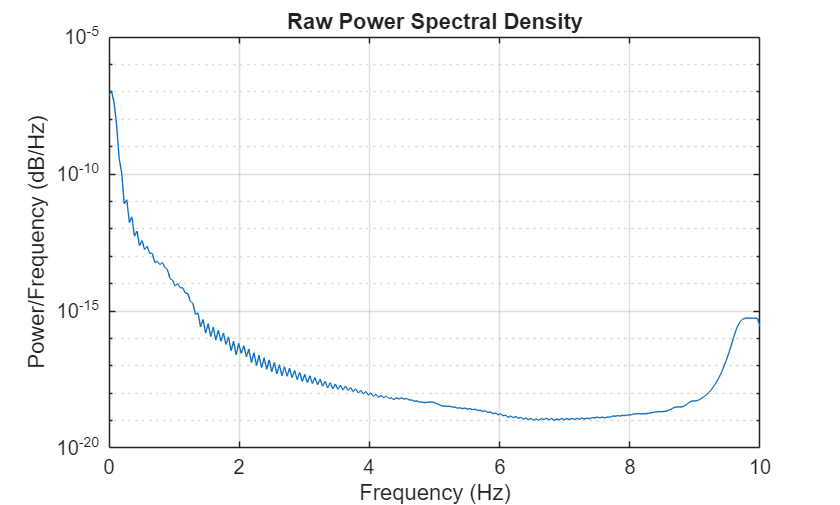

% calculate the power spectral density of the input signal to display
% frequencies of interst & what should be filtered

% calculate the PSD and plot the power on a log scale
[velocity_power, f] = pwelch(velocity_data, hann(256), 128, 512, fs);
semilogy(f, velocity_power)
title('Raw Power Spectral Density');
xlabel('Frequency (Hz)'); ylabel('Power/Frequency (dB/Hz)');
grid on;
xlim([0 fs/2]); % set the x axis to respect the nyquist frequency

% implement the FIR filter to isolate the frequencies of interest
% from several datasets, earthquake information from distant sensors
% is in the 0.3 - 6 Hz range, this bandpass filter removes the low
% frequency sensor drift and the high frequency noise
filter_order = 64;
filter_cutoff = [0.3 6]; %hz

%bandpass filter with very low frequency cutoff to remove DC offset and
%relatively low frequency to remove high frequency noise
bpf = fir1(filter_order, filter_cutoff/(fs/2), 'bandpass');

% apply the filter to the velocity data
velocity_filtered = filter(bpf, 1, velocity_data);

% remove the first few samples due to FIR startup behavior (messes up
% matlab axis auto scale)
velocity_filtered(1:filter_order) = 0;

% recalculate the PSD
[velocity_power_filtered, f_filtered] = pwelch(velocity_filtered, hann(256), 128, 512, fs);

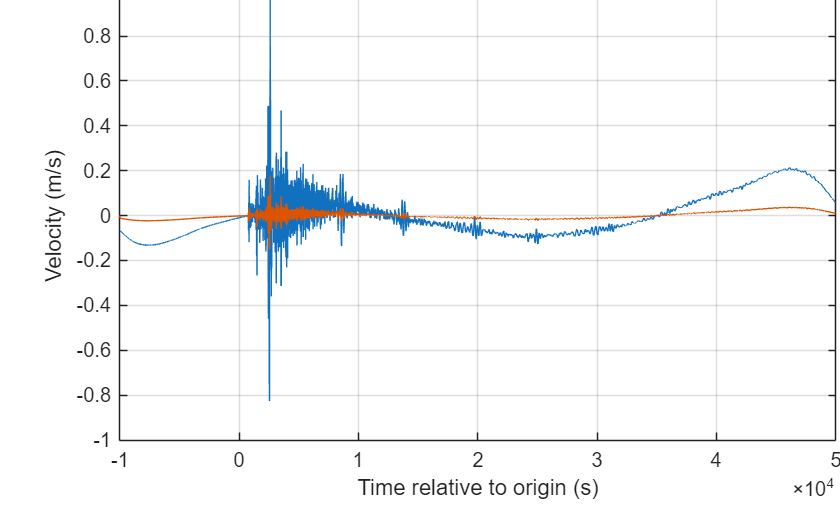

% compare the time domain and PSD plots post filter

% plot the raw time domain signal vs the filtered one to compare
figure;
plot(t, velocity_data);
hold on;
plot(t, velocity_filtered);
title('Time Domain — Pre vs. Post Filtering');
xlabel('Time relative to origin (s)'); 
ylabel('Velocity (m/s)');
grid on;

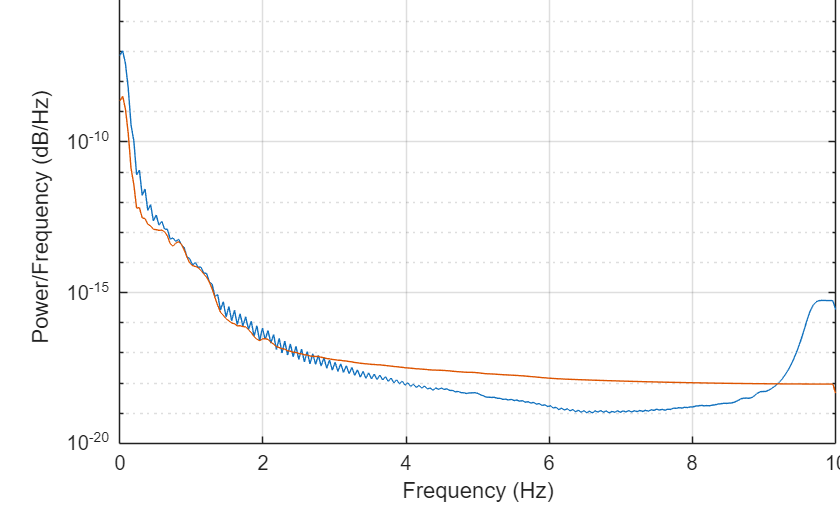


% plot the raw PSD vs filtered PSD
figure;
semilogy(f, velocity_power)
hold on;
semilogy(f_filtered, velocity_power_filtered)
title('Figure 2: Power Spectral Density — Pre vs Post Filtering');
xlabel('Frequency (Hz)'); ylabel('Power/Frequency (dB/Hz)');
grid on;

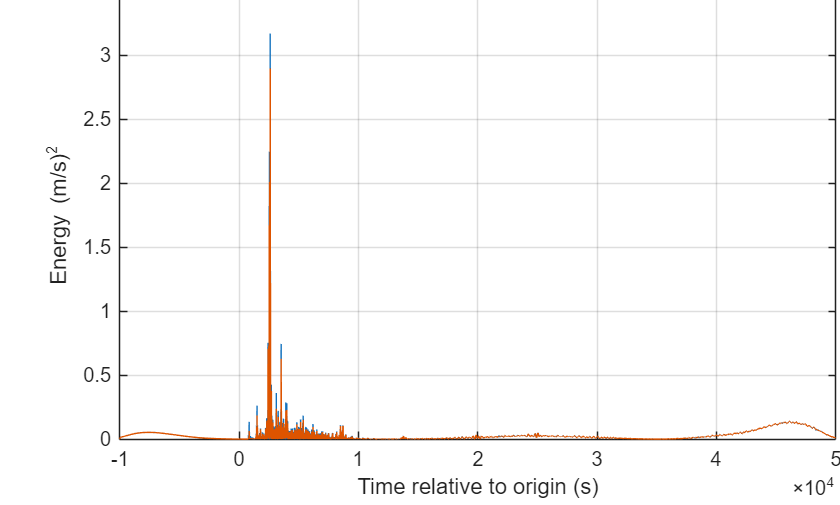

% square the data to get the energy of the signal
signal_energy = velocity_filtered .^ 2;

% apply  a moving average window to smooth the data
ma_window_size = 100;
smoothed_data = movmean(signal_energy, [ma_window_size-1 0]);

% plot the data before and after smoothing
figure;
plot(t, signal_energy);
title('Raw Signal Energy');
grid on;
hold on;
plot(t, smoothed_data);
title(sprintf('Raw vs Smoothed Signal Energy (%d-Sample Moving Average)', ma_window_size));
xlabel('Time relative to origin (s)'); 
ylabel('Energy (m/s)^2');

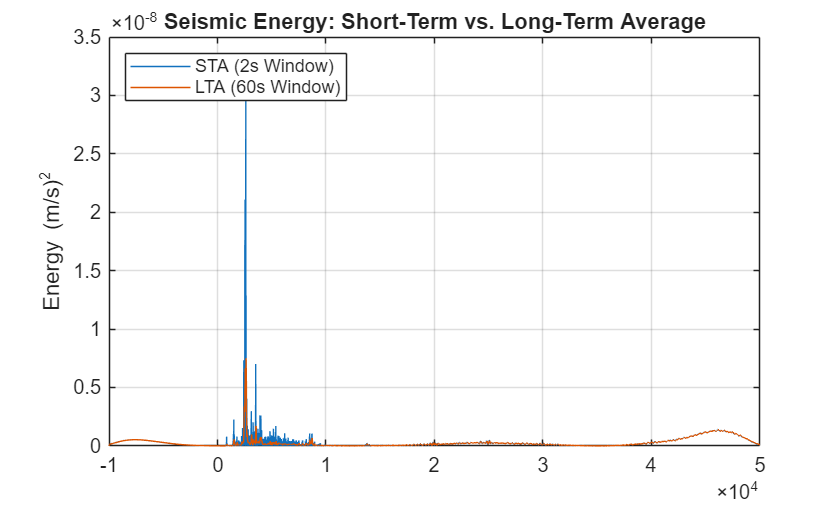

% define short and long term window sizes in seconds
sta_sec = 3;   
lta_sec = 60;  

% multiply windows sizes by samplnig frequency to get number of samples per
% window
sta_samples = round(sta_sec * fs);  
lta_samples = round(lta_sec * fs);  

% compute the moving average based on the short and long term windows
sta = movmean(signal_energy, [sta_samples-1 0]);
lta = movmean(signal_energy, [lta_samples-1 0]);

%calculate the ration between short and long term averages, if short term
%greatly outweighs the long term, an earthquake has been detected
sta_lta_ratio = sta ./ (lta);

% set the STA / LTA ratio threshold for earthquake detection
trigger_threshold = 10;

%plot the STA and LTA outputs
figure;
plot(t, sta,'DisplayName', 'STA (2s Window)');
hold on;
plot(t, lta, 'DisplayName', 'LTA (60s Window)');
title('Seismic Energy: Short-Term vs. Long-Term Average');
ylabel('Energy (m/s)^2');
legend('Location', 'northwest');
grid on;


%plot the ratio and the threshold to see earthquake detection point
figure;
plot(t, sta_lta_ratio, 'DisplayName', 'STA/LTA Ratio');
hold on;
yline(trigger_threshold, 'r--', 'Trigger Threshold');
title('Detection Trigger: STA / LTA Ratio');
xlabel('Time relative to origin (s)');
ylabel('Ratio');
legend('Location', 'northwest');
grid on;

Below is used to compare different filter orders and their metrics to find the optimal filter for our system. It is largely based on the process above.

filter_orders = [16, 32, 64];
n_orders      = length(filter_orders);

% number of STA / LTA samples based on of average time
sta_samples = round(sta_sec * fs);
lta_samples = round(lta_sec * fs);

% arbitrary clock speed used to calculate computational metrics
clock_freq  = 50e6;     

% cells to store signal at different points in processing loop
filtered_signals = cell(1, n_orders);
sta_signals      = cell(1, n_orders);
lta_signals      = cell(1, n_orders);
ratio_signals    = cell(1, n_orders);
filter_magnitude = cell(1, n_orders);
filter_frequency = cell(1, n_orders);

% arrays to store computational metrics of different filter orders
measured_runtime   = zeros(1, n_orders); 
quant_error        = zeros(1, n_orders);
detection_occurred = false(1, n_orders);
detection_time   = nan(1, n_orders);
stopband_attenuation   = zeros(1, n_orders);
macs_per_samp          = zeros(1, n_orders);
memory_usage          = zeros(1, n_orders);
max_throughput         = zeros(1, n_orders);
group_delay_ms         = zeros(1, n_orders);


% loop through all filter orders, saving data, and computing metrics
for i = 1:n_orders
    N = filter_orders(i);
    
    % generate bandpass filter based on cutoff frequency
    bpf = fir1(N, filter_cutoff / (fs/2), 'bandpass');

    % filter raw signal and measure actual execution time in ms
    tic;
    velocity_filtered = filter(bpf, 1, velocity_data);
    measured_runtime(i) = toc * 1000;
    
    % remove initial transient while FIR filter loads and add to cell
    velocity_filtered(1:N) = 0;
    filtered_signals{i} = velocity_filtered;

    % calculate signal energy and get short and long
    % term averages to detect earthquakes
    signal_energy = velocity_filtered .^ 2;
    sta = movmean(signal_energy, [sta_samples - 1, 0]);
    lta = movmean(signal_energy, [lta_samples - 1, 0]);
    ratio = sta ./ lta;
    
    % add the averages and ratios to the cells
    sta_signals{i}   = sta;
    lta_signals{i}   = lta;
    ratio_signals{i} = ratio;
    
    % remove startup transients again
    ratio(1:(N + lta_samples)) = 0;

    % get the index of the first STA  / LTA average that crossed the
    % detection threshold
    threshold_crossed_index = find(ratio > trigger_threshold, 1, 'first');
    % check to see if threshold was crossed for data set and save it for
    % plotting
    if ~isempty(threshold_crossed_index)
        detection_occurred(i) = true;
        detection_time(i)   = t(threshold_crossed_index);
    end

    % get the frequency response and stopband attenuation of different
    % filter orders. 
    [magnitude, frequency] = freqz(bpf, 1, 4096, fs);
    filter_magnitude_dB = 20 * log10(abs(magnitude));
    filter_magnitude{i} = filter_magnitude_dB;
    filter_frequency{i} = frequency;
    
    % check within 20% of the stopband frequency and get the maximum
    % attenuation in the range
    stopband_index = (frequency <= filter_cutoff(1)*0.8) | (frequency >= filter_cutoff(2) + 1.2);
    if any(stopband_index)
        stopband_attenuation(i) = abs(max(filter_magnitude_dB(stopband_index))); 
    end
    

    % calculate theoretical computational metrics for different filter orders

    % MAC instructions scale linearly with FIr filter taps
    macs_per_samp(i)   = N + 1;

    % memory footprint for FIR filter 
    % each tap requires 1 memory location for the coefficient and 1 for the
    % histroy of previous filter outputs. Assuming 16 bit precision, we
    % multiply the memory used by 2 to get the number of bytes used for a
    % given filter order
    memory_usage(i)   = 2 * (N + 1) * 2;    

    % calculate the throghput using the arbitrary clock frequency
    max_throughput(i)  = clock_freq / macs_per_samp(i);
    
    % calculate the group delay based on the filter order
    % group delay for a FIR filter scales with the number of taps divided
    % by 2 and the sampling frequency. Multiply by 1000 to put in ms
    group_delay_ms(i)  = (N / 2) / fs * 1000;
    
    % calculate the error caused by quantization when using 16 bit
    % precision. Take the floating point coefficients of the filter, round
    % them to whole numbers and divide by the 16 bit precision. Get the
    % magnitude of the difference throughout the whole vector using the
    % norm() function
    bpf_quantized = round(bpf * (2^15 - 1)) / (2^15 - 1);
    quant_error(i) = norm(bpf - bpf_quantized); 
end

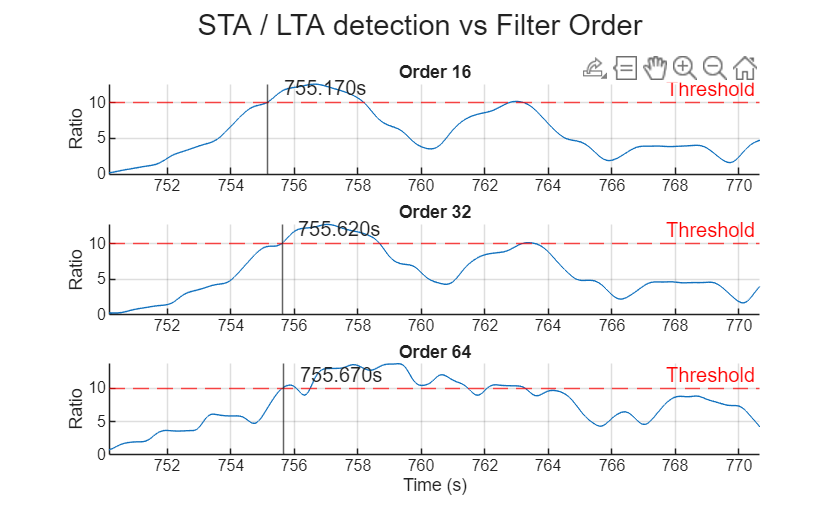

% zoom in on detection point of STA / LTA ratio to compare different
% filters
valid_detections = detection_time(detection_occurred);
if ~isempty(valid_detections)
    zoom_pre_sec  = 5;  
    zoom_post_sec = 15; 
    fixed_xlim_zoom = [max(min(t), min(valid_detections) - zoom_pre_sec), min(max(t), max(valid_detections) + zoom_post_sec)];
else
    fixed_xlim_zoom = [min(t), max(t)];
end


figure;
for i = 1:n_orders
    subplot(n_orders, 1, i);
    hold on; 
    grid on;
    plot(t, ratio_signals{i});
    yline(trigger_threshold, 'r--', 'Threshold');
    if detection_occurred(i)
        xline(detection_time(i));
        text(detection_time(i) + 0.5, trigger_threshold*1.2, sprintf('%.3fs', detection_time(i)));
    end
    title(sprintf('Order %d', filter_orders(i)));
    ylabel('Ratio');
    xlim(fixed_xlim_zoom);
    if i == n_orders, xlabel('Time (s)'); end
end

sgtitle('STA / LTA detection vs Filter Order');

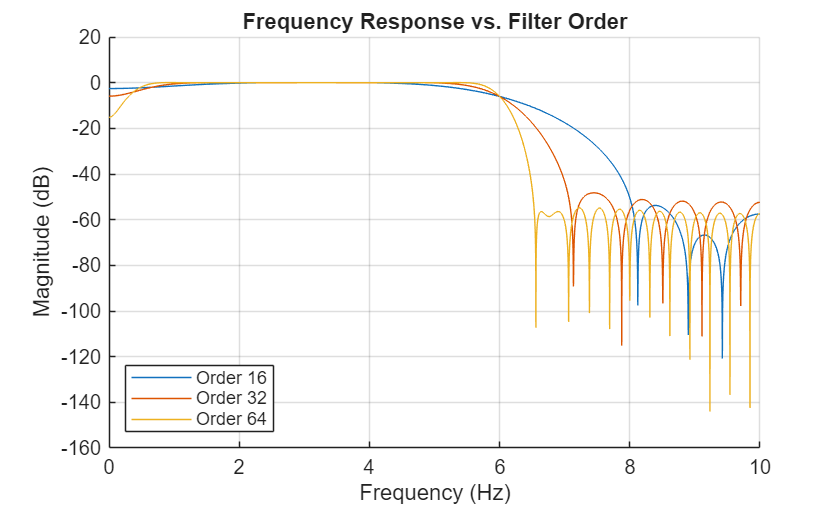

% filter frequency response 
figure;
hold on; 
grid on;
colors = lines(n_orders);
for i = 1:n_orders
    plot(filter_frequency{i}, filter_magnitude{i}, 'Color', colors(i,:), 'DisplayName', sprintf('Order %d', filter_orders(i)));
end
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Frequency Response vs. Filter Order');
legend('Location', 'southwest')

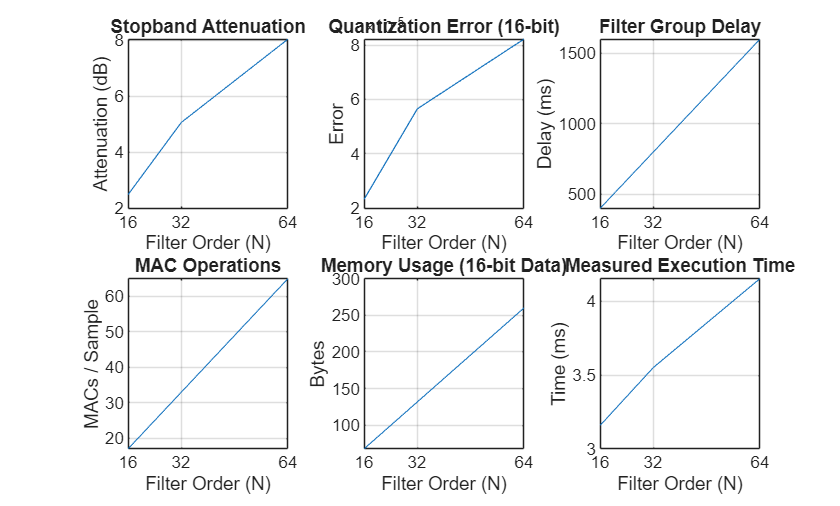


%subplot of different metrics
figure;

% stopband attenuation
subplot(2,3,1); 
plot(filter_orders, stopband_attenuation);
grid on; 
title('Stopband Attenuation');
xlabel('Filter Order (N)'); 
ylabel('Attenuation (dB)'); 
xticks(filter_orders); 
xticklabels(filter_orders);

% quantization error
subplot(2,3,2); 
plot(filter_orders, quant_error);
grid on; 
title('Quantization Error (16-bit)');
xlabel('Filter Order (N)'); 
ylabel('Error'); 
xticks(filter_orders); 
xticklabels(filter_orders);

% group delay
subplot(2,3,3); 
plot(filter_orders, group_delay_ms);
grid on; 
title('Filter Group Delay');
xlabel('Filter Order (N)'); 
ylabel('Delay (ms)'); 
xticks(filter_orders); 
xticklabels(filter_orders);

% MAC operations
subplot(2,3,4); 
plot(filter_orders, macs_per_samp);
grid on;
title('MAC Operations');
xlabel('Filter Order (N)');
ylabel('MACs / Sample');
xticks(filter_orders);
xticklabels(filter_orders);

% memory usage
subplot(2,3,5); 
plot(filter_orders, memory_usage);
grid on; 
title('Memory Usage (16-bit Data)');
xlabel('Filter Order (N)'); 
ylabel('Bytes');
xticks(filter_orders); 
xticklabels(filter_orders);

% measured execution time
subplot(2,3,6);
plot(filter_orders, measured_runtime);
grid on;
title('Measured Execution Time');
xlabel('Filter Order (N)');
ylabel('Time (ms)'); 
xticks(filter_orders); 
xticklabels(filter_orders);

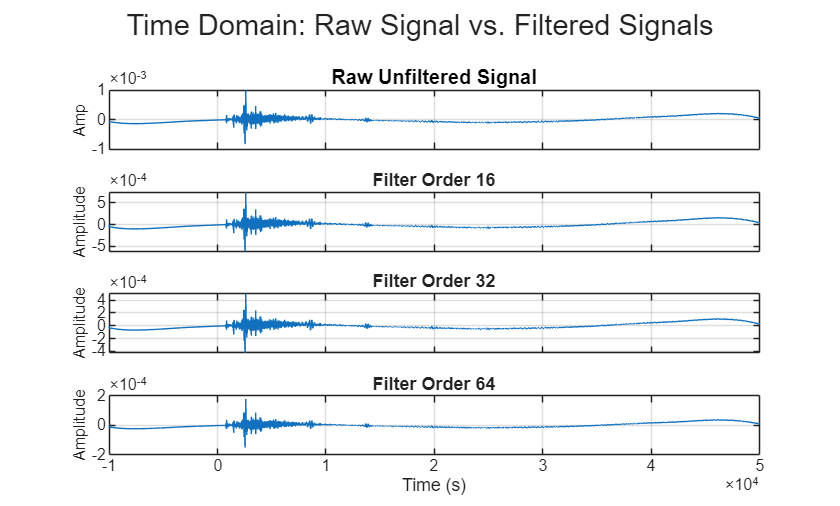

% plot the raw, unfiltered signal
figure;
subplot(n_orders + 1, 1, 1);
plot(t, velocity_data);
grid on; 
title('Raw Unfiltered Signal', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'k');
ylabel('Amp', 'FontSize', 8);
% remove the x labels except for the bottom plot
xticklabels({});

% loop through the other filter orders and plot the time domain
for i = 1:n_orders
    subplot(n_orders + 1, 1, i + 1);
    
    plot(t, filtered_signals{i});
    grid on;
    ylabel('Amplitude', 'FontSize', 8);
    title(sprintf('Filter Order %d', filter_orders(i)), 'FontSize', 9);
    
    % add the axis title and tick labels to the final plot
    if i == n_orders
        xlabel('Time (s)');
    else
        xticklabels({});
    end
end
sgtitle('Time Domain: Raw Signal vs. Filtered Signals');

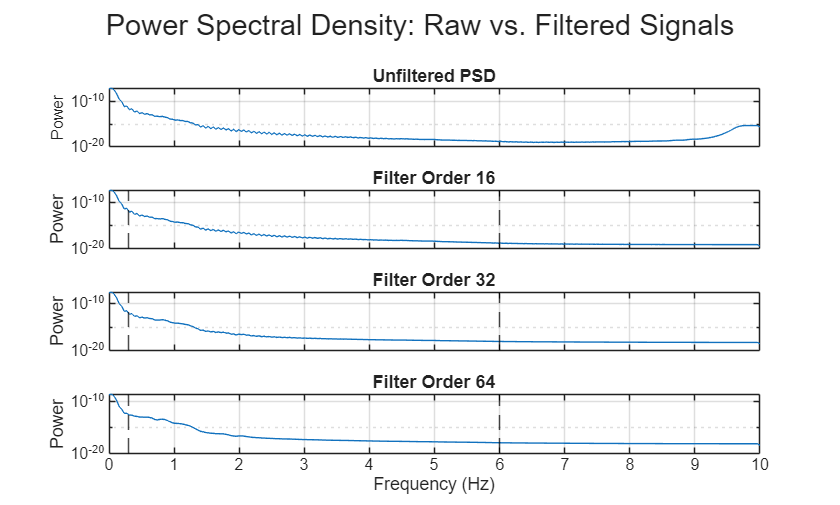



% plot the raw, unfiltered, PSD data
figure;
subplot(n_orders + 1, 1, 1);
semilogy(f, velocity_power);
grid on; 
xlim([0, fs/2]);
title('Unfiltered PSD');
ylabel('Power', 'FontSize', 8);
xticklabels({});

% loop through the other filter orders and plot the PSD data
for i = 1:n_orders
    subplot(n_orders + 1, 1, i + 1);
    
    [pwr, f_psd] = pwelch(filtered_signals{i}, hann(256), 128, 512, fs);
    
    semilogy(f_psd, pwr);
    hold on; 
    title(sprintf('Filter Order %d', filter_orders(i)), 'FontSize', 9);
    ylabel('Power');
    xlim([0, fs/2]);
    grid on;
    
    % add vertical lines at the filter cutoffs to visualize the filter behavior
    xline(filter_cutoff(1), 'k--');
    xline(filter_cutoff(2), 'k--');

        
    % add the axis title and tick labels to the final plot
    if i == n_orders
        xlabel('Frequency (Hz)');
    else
        xticklabels({});
    end
    hold off;
end

sgtitle('Power Spectral Density: Raw vs. Filtered Signals');